clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
WindData=data.WindData;
FWT=data.FWT;
G=[FWT(1,1) FWT(1,2)];
%G=tf(G);
Gd = FWT(1,3);
s = tf('s');

wB1=0.1*2*pi; % desired closed-loop bandwidth
A=1/1000 % desired disturbance attenuation inside bandwidth

A = 1.0000e-03

M=3 ; % desired bound on hinfnorm(S)
%Wp11=tf([1/sqrt(M) (2*wB1)/sqrt(M) wB1^2],[1 2*wB1*sqrt(A) A*wB1*wB1])
Wp11=(((s/sqrt(M))+wB1)^2)/((s+(wB1*sqrt(A)))^2)

Wp11 =
 
     s^2 + 2.177 s + 1.184
  ---------------------------
  3 s^2 + 0.1192 s + 0.001184
 
Continuous-time transfer function.



%Wp11=tf([1/M wB1],[1 wB1*A])
Wp=[Wp11]; %
%Sensitivity weight
%tau11 = 0.1;
tau22 = 1000;
k2 = 0.0000001;
a2=0.0001

a2 = 1.0000e-04


tau11= 0.1;
%tau21 = 10;
k1 = 10000;
a1 = 0.1;

Wu22 = a2*(1/k2)*((tau22*k2*s+1)/(tau22*s+1))  %lead lag filter

Wu22 =
 
  0.1 s + 1000
  ------------
   1000 s + 1
 
Continuous-time transfer function.



%Wu22 = (5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu11 = a1*((k1*tau11*s+1)/(tau11*s+1)) %lead lag filter

Wu11 =
 
  100 s + 0.1
  -----------
   0.1 s + 1
 
Continuous-time transfer function.





Wu=[Wu11 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []



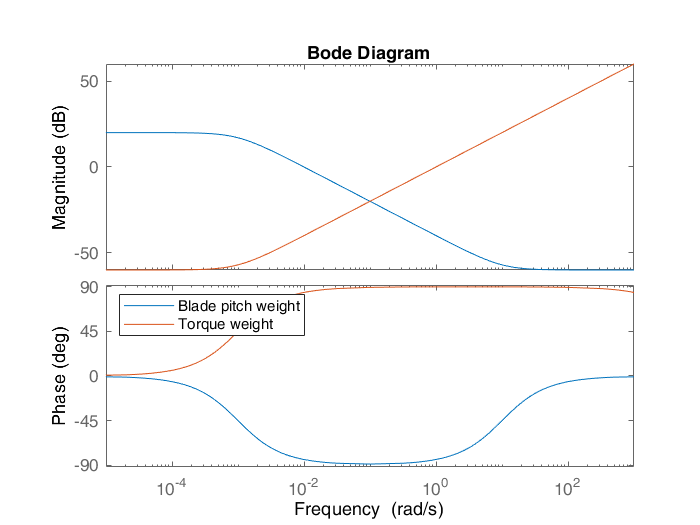


bode(1/Wu11,1/Wu22)
legend('Blade pitch weight','Torque weight','location','northwest')


P11=Wp*Gd;
P12=Wp*-G;
P21=[0;0];
P22=Wu;
P31=Gd;
P32=-G;

P=[P11 P12; P21 P22;P31 P32];
%P=tf(P);
[K,CL,GAM,INFO] = hinfsyn(P,1,2);
CL=minreal(CL);

36 states removed.


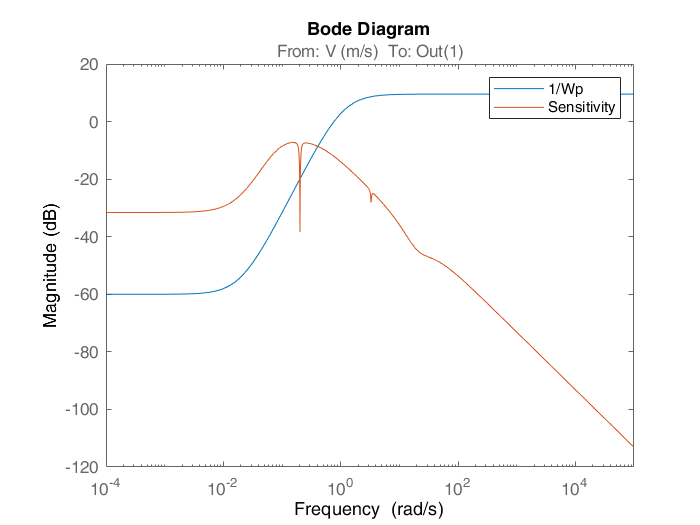


Sens=(1/Wp)*CL(1);
KS1=(1/(Wu11))*CL(2);
KS2=(1/(Wu22))*CL(3);

figure()
bodemag(1/Wp,Sens)
legend('1/Wp', 'Sensitivity')

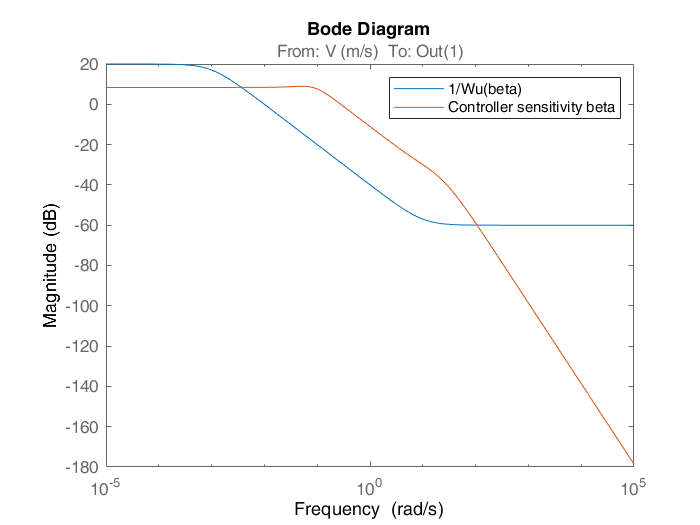


figure()
bodemag(1/Wu11,KS1)
legend('1/Wu(beta)', 'Controller sensitivity beta')

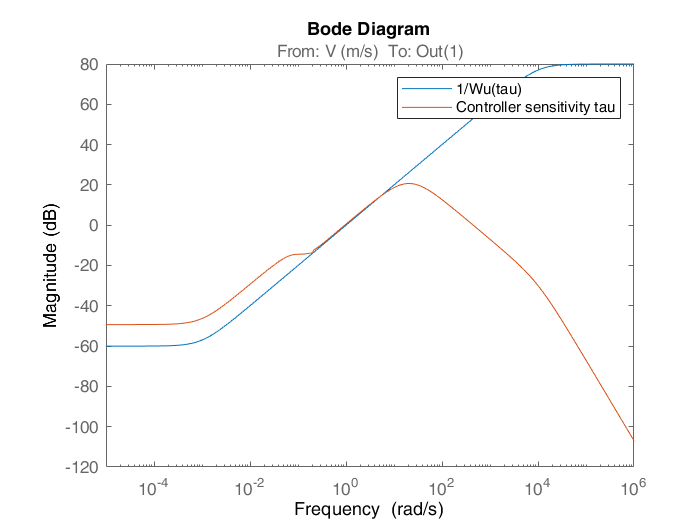


figure()
bodemag(1/Wu22,KS2)
legend('1/Wu(tau)', 'Controller sensitivity tau')

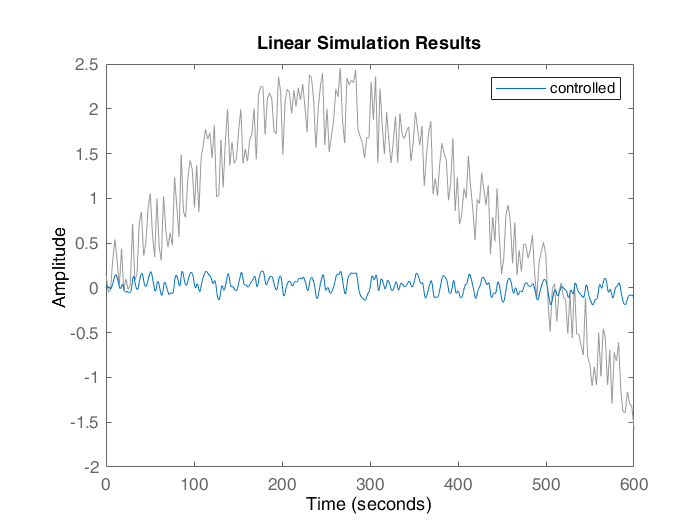


t = WindData(:,1);
input = WindData(:,2);

figure()
lsim(Sens,input,t)
legend('controlled')

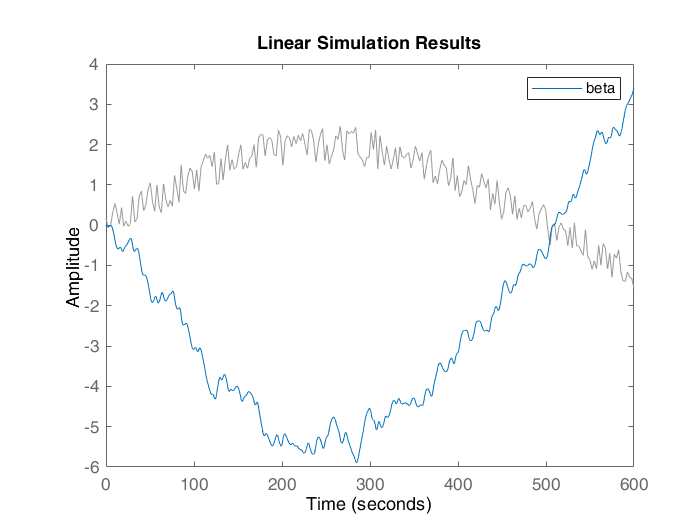


figure()
lsim(KS1,input,t)
legend('beta')

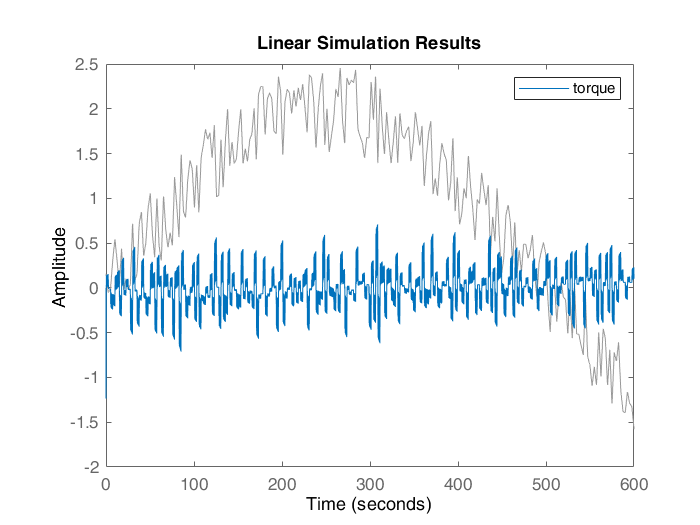


figure()
lsim(KS2,input,t)
legend('torque')



Ts = (t(end)-t(1))/(numel(t)-1);

The end operator must be used within an array index expression.

y = fft(input);
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);
plot(f,abs(y))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')



